clc
clear all
syms Omega k b m  a w_h_sq w_theta_sq x_theta_bar mu g_prime k Lh La Mh r_theta_bar_sq Ma 
b= 3;  %ft
m = 269.0; %slugs/ft
a = -0.2;
w_h = 10  %wh^2

w_h = 10

w_h = 10

w_h = 10

w_theta = 25; %wtheta^2
x_theta_bar = 0.1;
mu = 20.0;
% g_prime = 0;
k = 1./linspace(0.001,5.0,100)

k = 	1.0e+03 *

    1.0000    0.0194    0.0098    0.0066    0.0049    0.0039    0.0033    0.0028    0.0025    0.0022    0.0020    0.0018    0.0016    0.0015    0.0014    0.0013    0.0012    0.0012    0.0011    0.0010    0.0010    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004


1./k

ans =     0.0010    0.0515    0.1020    0.1525    0.2030    0.2535    0.3040    0.3545    0.4050    0.4555    0.5059    0.5564    0.6069    0.6574    0.7079    0.7584    0.8089    0.8594    0.9099    0.9604    1.0109    1.0614    1.1119    1.1624    1.2129    1.2634    1.3139    1.3644    1.4149    1.4654    1.5158    1.5663    1.6168    1.6673    1.7178    1.7683    1.8188    1.8693    1.9198    1.9703    2.0208    2.0713    2.1218    2.1723    2.2228    2.2733    2.3238    2.3743    2.4248    2.4753


r_theta_bar = 0.5; %rtheta_bar^2
Mh = 0.5;
Ma = 3./8 -1i.*(1./k);
for n = 1:length(k)
ck = 1- ((0.165.*k(n))./(k(n)-0.0455.*1i))-((0.355.*k(n))./(k(n)-0.3.*1i));
Ma = 3./8 - 1i.*(1./k(n));
Lh = 1 - ((1i.*(2.*ck))./k(n));
La = 0.5 - ((1i.*(1+2.*ck))./k(n))-(2.*ck./(k(n)).^2);
A_b =  mu.*((1-Omega.*((w_h.^2)./(w_theta.^2))))+Lh;
B_b = (mu.*x_theta_bar)+ La - Lh.*(0.5+a);
D_b = (mu.*x_theta_bar)+ Mh - Lh.*(0.5+a);
E_b = (mu.*(r_theta_bar.^2)).*(1-Omega) - (Mh.*(0.5+a)) + Ma - La.*(0.5+a) + Lh.*((0.5+a).^2);
Eq = A_b.*E_b - B_b.*D_b;
omega(:,n) = eval(solve(Eq,Omega));
end
omega

omega =    0.9788 - 0.0001i   0.9790 - 0.0035i   0.9797 - 0.0069i   0.9808 - 0.0104i   0.9823 - 0.0139i   0.9843 - 0.0174i   0.9867 - 0.0209i   0.9896 - 0.0245i   0.9929 - 0.0281i   0.9967 - 0.0318i   1.0009 - 0.0355i   1.0056 - 0.0393i   1.0109 - 0.0432i   1.0166 - 0.0471i   1.0228 - 0.0511i   1.0295 - 0.0552i   1.0368 - 0.0594i   1.0446 - 0.0636i   1.0529 - 0.0679i   1.0619 - 0.0723i   1.0713 - 0.0768i   1.0814 - 0.0813i   1.0921 - 0.0859i   1.1035 - 0.0905i   1.1154 - 0.0952i   1.1280 - 0.0999i   1.1413 - 0.1047i   1.1552 - 0.1095i   1.1699 - 0.1143i   1.1852 - 0.1191i   1.2013 - 0.1240i   1.2181 - 0.1287i   1.2356 - 0.1335i   1.2540 - 0.1382i   1.2731 - 0.1428i   1.2930 - 0.1473i   1.3137 - 0.1517i   1.3352 - 0.1560i   1.3576 - 0.1601i   1.3808 - 0.1640i   1.4049 - 0.1677i   1.4299 - 0.1712i   1.4557 - 0.1744i   1.4824 - 0.1773i   1.5100 - 0.1799i   1.5385 - 0.1821i   1.5680 - 0.1839i   1.5983 - 0.1852i   1.6296 - 0.1860i   1.6618 - 0.1863i
   6.6167 - 0.0003i   6.6164 - 0.0171i   

w = w_theta./sqrt(real(omega))

w =    25.2690   25.2661   25.2576   25.2435   25.2239   25.1986   25.1678   25.1313   25.0893   25.0417   24.9885   24.9297   24.8653   24.7954   24.7200   24.6390   24.5526   24.4607   24.3635   24.2610   24.1532   24.0402   23.9222   23.7992   23.6714   23.5388   23.4016   23.2599   23.1139   22.9638   22.8096   22.6517   22.4902   22.3252   22.1570   21.9858   21.8118   21.6352   21.4562   21.2751   21.0920   20.9071   20.7208   20.5332   20.3446   20.1551   19.9650   19.7744   19.5837   19.3931
    9.7190    9.7191    9.7196    9.7205    9.7217    9.7232    9.7250    9.7271    9.7296    9.7324    9.7356    9.7390    9.7428    9.7469    9.7513    9.7560    9.7611    9.7664    9.7721    9.7780    9.7843    9.7908    9.7977    9.8048    9.8123    9.8200    9.8281    9.8364    9.8450    9.8540    9.8632    9.8727    9.8826    9.8927    9.9031    9.9139    9.9249    9.9363    9.9480    9.9600    9.9723    9.9850    9.9980   10.0113   10.0250   10.0390   10.0533   10.0680   10.0830   10

g = real(((w_theta.^2).*1i - omega.*(w.^2).*1i)./(w_theta.^2))

g =    -0.0001   -0.0036   -0.0071   -0.0106   -0.0141   -0.0176   -0.0212   -0.0247   -0.0283   -0.0319   -0.0355   -0.0391   -0.0427   -0.0463   -0.0500   -0.0536   -0.0573   -0.0609   -0.0645   -0.0681   -0.0716   -0.0752   -0.0786   -0.0820   -0.0854   -0.0886   -0.0918   -0.0948   -0.0977   -0.1005   -0.1032   -0.1057   -0.1080   -0.1102   -0.1122   -0.1139   -0.1155   -0.1168   -0.1179   -0.1188   -0.1194   -0.1197   -0.1198   -0.1196   -0.1191   -0.1183   -0.1173   -0.1159   -0.1141   -0.1121
   -0.0001   -0.0026   -0.0051   -0.0077   -0.0102   -0.0128   -0.0154   -0.0180   -0.0206   -0.0232   -0.0259   -0.0286   -0.0313   -0.0341   -0.0369   -0.0397   -0.0426   -0.0455   -0.0485   -0.0516   -0.0547   -0.0578   -0.0610   -0.0643   -0.0676   -0.0710   -0.0745   -0.0780   -0.0816   -0.0853   -0.0891   -0.0930   -0.0969   -0.1010   -0.1051   -0.1093   -0.1137   -0.1181   -0.1226   -0.1273   -0.1321   -0.1370   -0.1421   -0.1472   -0.1526   -0.1581   -0.1637   -0.1695   -0.1755   -0

V = w.*b./k

V =     0.0758    3.9032    7.7281   11.5478   15.3598   19.1616   22.9507   26.7245   30.4805   34.2160   37.9287   41.6159   45.2752   48.9041   52.5000   56.0605   59.5832   63.0657   66.5058   69.9010   73.2493   76.5485   79.7966   82.9915   86.1315   89.2148   92.2397   95.2048   98.1087  100.9501  103.7279  106.4411  109.0889  111.6707  114.1859  116.6341  119.0152  121.3289  123.5754  125.7549  127.8678  129.9144  131.8956  133.8119  135.6643  137.4539  139.1817  140.8491  142.4575  144.0083
    0.0292    1.5015    2.9739    4.4467    5.9199    7.3937    8.8683   10.3438   11.8203   13.2981   14.7771   16.2577   17.7399   19.2239   20.7097   22.1976   23.6877   25.1802   26.6750   28.1725   29.6727   31.1757   32.6818   34.1909   35.7033   37.2191   38.7384   40.2613   41.7880   43.3187   44.8534   46.3923   47.9355   49.4833   51.0356   52.5928   54.1549   55.7222   57.2947   58.8726   60.4561   62.0454   63.6407   65.2420   66.8497   68.4639   70.0846   71.7122   73.3468   74

plot(V(2,:),g(2,:),"ro")
hold on
plot(V(1,:),g(1,:)," bo ")
grid on
Vf = interp1([-0.00495264 0.00425538],[165.721 166.692],0)

Vf = 166.2433

Vf = 166.2433

Vf = 166.2433

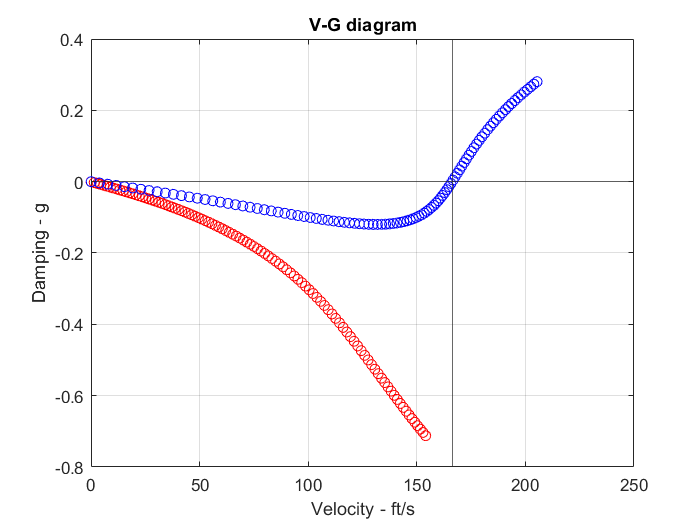

xline(Vf)
yline(0)
xlabel('Velocity - ft/s')
ylabel('Damping - g')
title('V-G diagram')
hold off  

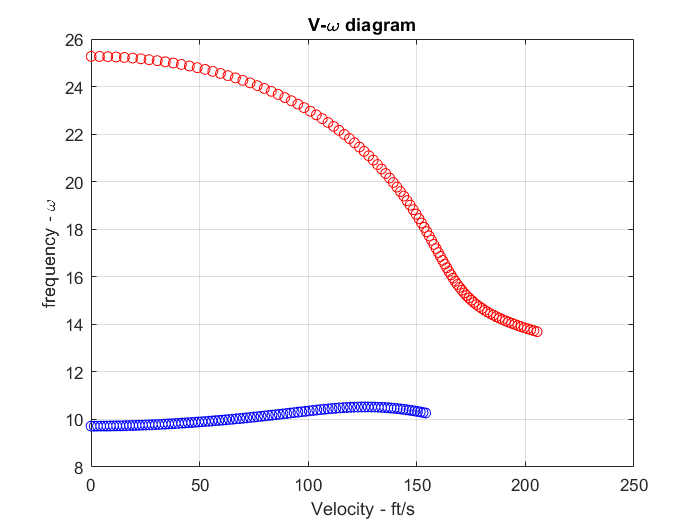

plot(V(1,:),w(1,:),"ro")
hold on
plot(V(2,:),w(2,:),"bo")
title('V-\omega diagram')
xlabel('Velocity - ft/s')
ylabel('frequency - \omega')
grid on